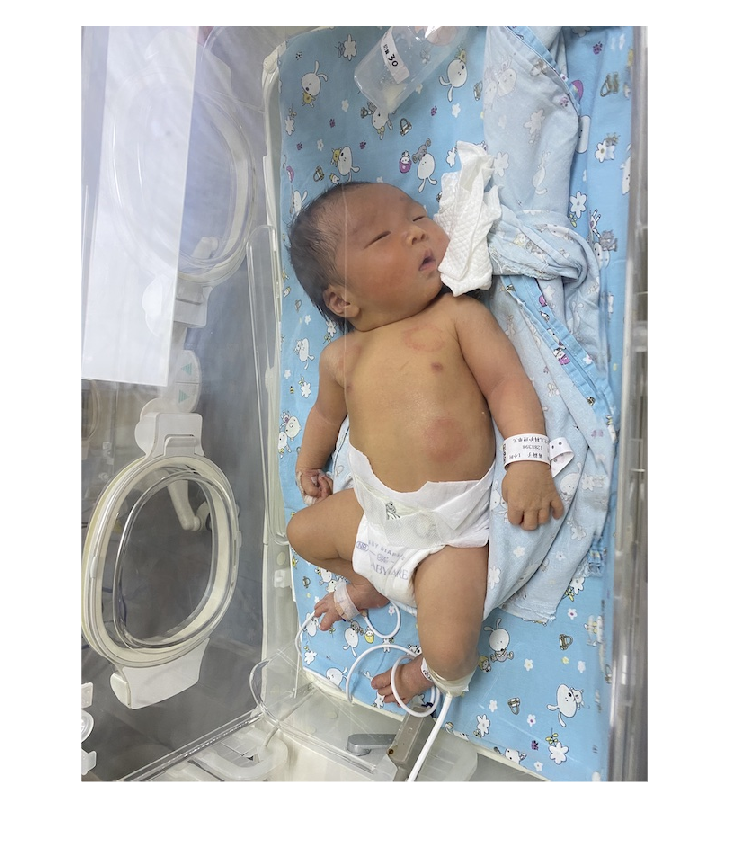

% Clear the workspace and console
clc; clear;

% 读取原始图像数据
origin = imread("baby.jpg");
imshow(origin);

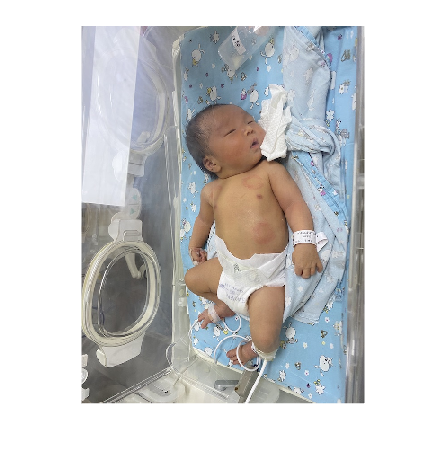

%Nearest Neighbor
near1(:,:,1)=origin(1:2:end,1:2:end,1);
near1(:,:,2)=origin(1:2:end,1:2:end,2);
near1(:,:,3)=origin(1:2:end,1:2:end,3);
imshow(near1);

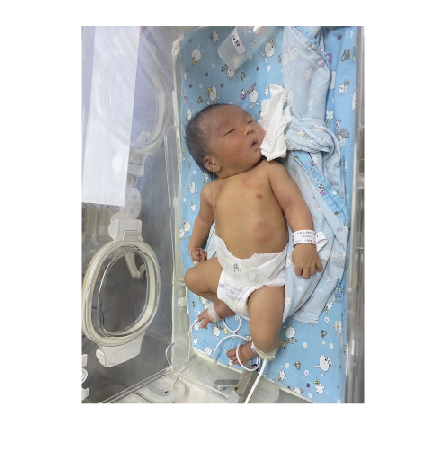

%Area
near2(:,:,1)=origin(1:2:end,2:2:end,1);
near2(:,:,2)=origin(1:2:end,2:2:end,2);
near2(:,:,3)=origin(1:2:end,2:2:end,3);

near3(:,:,1)=origin(2:2:end,1:2:end,1);
near3(:,:,2)=origin(2:2:end,1:2:end,2);
near3(:,:,3)=origin(2:2:end,1:2:end,3);


near4(:,:,1)=origin(2:2:end,2:2:end,1);
near4(:,:,2)=origin(2:2:end,2:2:end,2);
near4(:,:,3)=origin(2:2:end,2:2:end,3);
Area(:,:,1)= (double(near1(:,:,1))+double(near2(:,:,1))+double(near3(:,:,1))+double(near4(:,:,1)))/4;
Area(:,:,2)= (double(near1(:,:,2))+double(near2(:,:,2))+double(near3(:,:,2))+double(near4(:,:,2)))/4;
Area(:,:,3)= (double(near1(:,:,3))+double(near2(:,:,3))+double(near3(:,:,3))+double(near4(:,:,3)))/4;
imshow(uint8(Area));

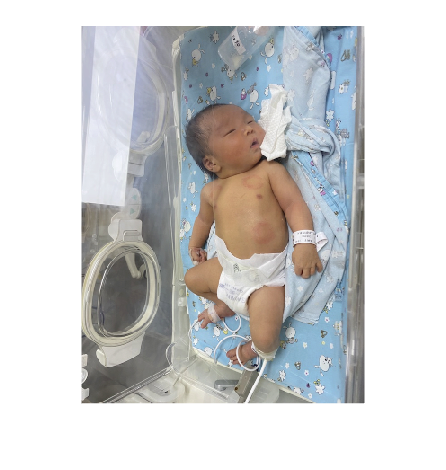

%Bilinear
Bill(:,:,1)=near3(:,:,1)*(2/9)+near4(:,:,1)*(1/9)+near1(:,:,1)*(4/9)+near2(:,:,1)*(2/9);
Bill(:,:,2)=near3(:,:,2)*(2/9)+near4(:,:,2)*(1/9)+near1(:,:,2)*(4/9)+near2(:,:,2)*(2/9);
Bill(:,:,3)=near3(:,:,3)*(2/9)+near4(:,:,3)*(1/9)+near1(:,:,3)*(4/9)+near2(:,:,3)*(2/9);
imshow(Bill);